# Static Cascaded Control of a Quadcopter's Position and Attitude

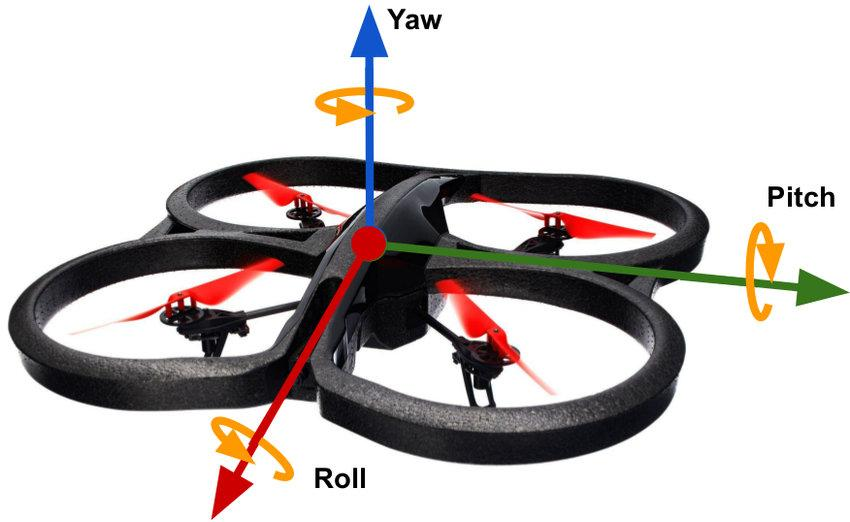

## Nomenclature

	Inertial frame								$\bar{N} = \{\hat{x}_N, \hat{y}_N, \hat{z}_N\}$

	Body frame								$\bar{B} = \{\hat{x}_B, \hat{y}_B, \hat{z}_B\}$

	Thrust constant							$K_t$

	Body mass								$m$

	Gravity constant							$g$

	Wing length								$l$

	Inertia matrix								$\bar{I}$

	Propeller Thrust vector						$T_p$

	Propeller Torque vector						$\tau_p$

	Position vector							$\hat{r}$

	Velocity vector 							$\dot{\hat{r}}$

	Attitude of Body as DCM 					$R_{BN} = R_{NB}^T$

	Attitude of Body as Euler Angles	 			$q$

	Rotational velocity of Body w.r.t Inertial frame	$\hat{\omega}$

*pre-superscript denotes the frame the vector is defined in.

## Dynamics

Forces:

	
$$^NT_p = R_{NB}\;\hat{z}_{B}\; K_t \Sigma^4_{i=1}u_i^2$$


	
$$^N\tau_p = K_t l\pmatrix{1 & 0 & -1 & 0 \cr 0 & -1 & 0 & 1 \cr -1 & 1 & -1 & 1}u^Tu$$


	
$$F_g = -mg \hat{z}_N$$


	
$$F_w = \alpha\hat{x}_N + \beta\hat{y}_N$$


Let $X = \pmatrix{\hat{r} \cr \dot{\hat{r}} \cr q \cr \hat{\omega}}$

Then,

	
$$\dot{x_1} = x_2$$


	
$$\dot{x_2} = T_p + F_g + F_w$$


	
$$\dot{x_3} = x_4$$


	
$$\dot{x_4} = \bar{I}^{-1}(-[\tilde{\hat{\omega}}]\bar{I}\hat{\omega}+^B\tau_p)$$


## Analysis

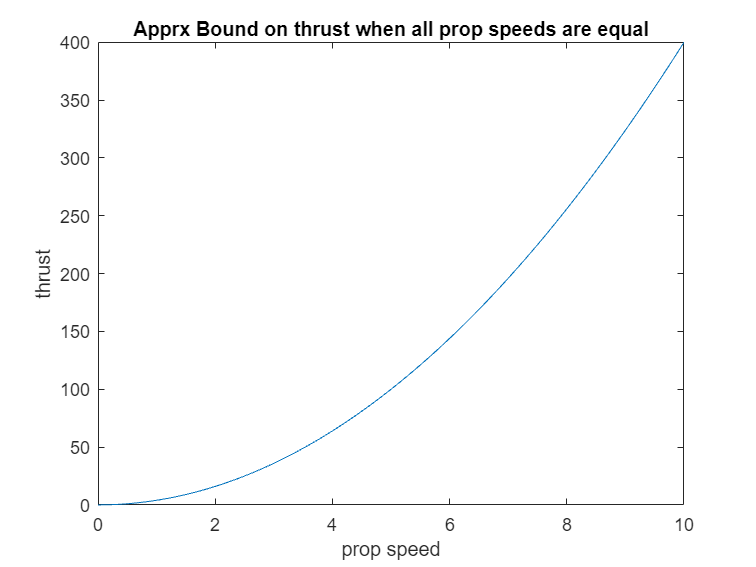

n_samples = 100;
x_max = 10;
X = linspace(0, x_max, n_samples);
T = 4 * X.^2;

figure 
plot(X, T)
title("Apprx Bound on thrust when all prop speeds are equal")
xlabel("prop speed")
ylabel("thrust")

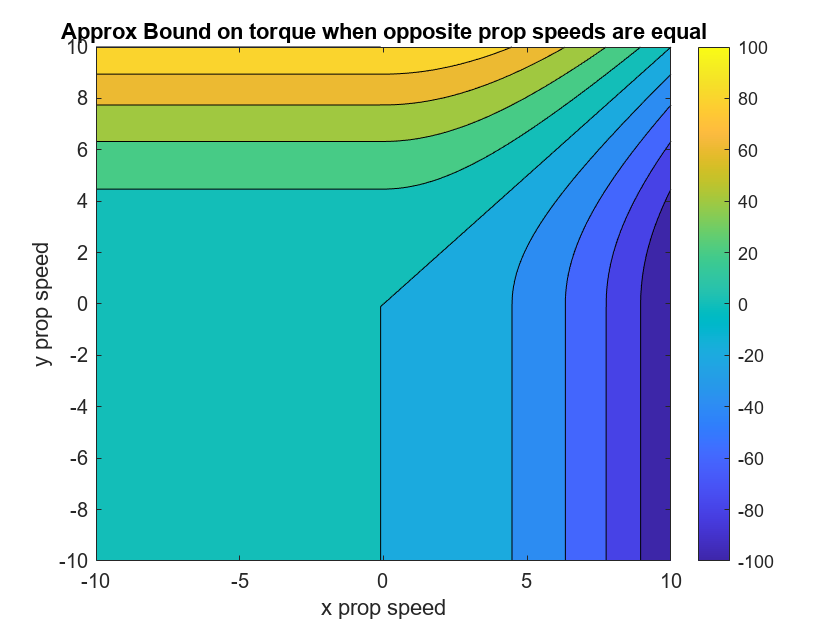

x_max = 10;
y_max = 10;
x = linspace(-x_max, x_max);
y = linspace(-y_max, y_max);
[X,Y] = meshgrid(x, y);
T = max(Y, zeros(size(Y))).^2 - max(X, zeros(size(X))).^2;

figure 
contourf(X, Y, T)
title("Approx Bound on torque when opposite prop speeds are equal")
xlabel("x prop speed")
ylabel("y prop speed")
colorbar()

## Simulation

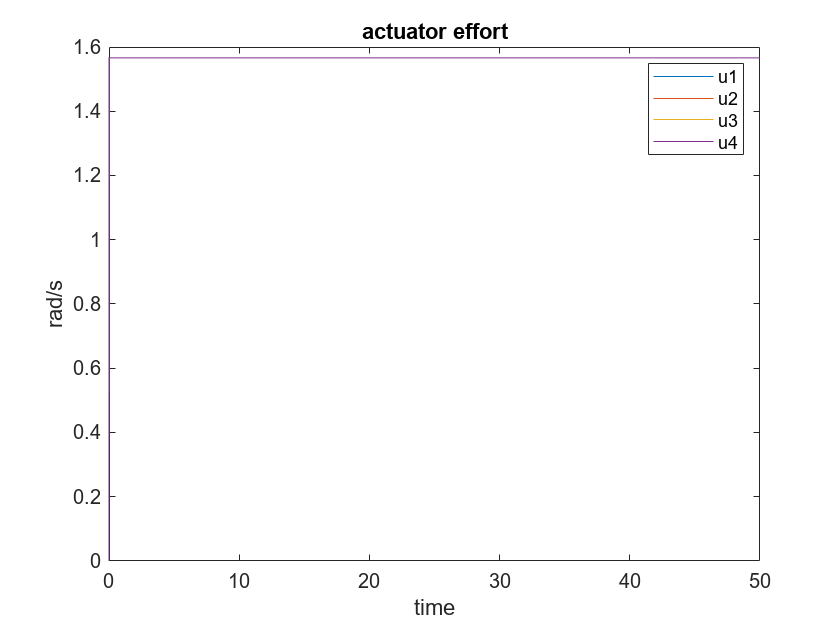

Kt = 5;
max_time = 50;
n_samples = max_time / 0.001;
t_space = linspace(0, max_time, n_samples);

dt = max_time / n_samples;

% Gains & constants
hover_throttle = sqrt(9.81 / 4);

K_att = 50 * pinv([1 0 -1 0;
				   0 -1 0 1; 
				  -10 10 -10 10]);

K_rate = 35 * pinv([1 0 -1 0;
					 0 -1 0 1; 
					-10 10 -10 10]);

K_q = 0.0001;

K_zp = 0.01 * ones(4,1);
K_zd = 0.02 * ones(4,1);

% histories
u_hist = zeros(4, n_samples);
r_hist = zeros(3, n_samples);
rdot_hist = zeros(3, n_samples);
rddot_hist = zeros(3, n_samples);
q_hist = zeros(3, n_samples);
omega_hist = zeros(3, n_samples);
omegadot_hist = zeros(3, n_samples);

% set initial condition
r_r = [1; 0; 0];
q_r = K_q * [r_hist(2, 1) - r_r(2); -r_hist(1,1) + r_r(1); 0];
% r_hist(3, 1) = 1;
% q_hist(1, 1) = -0.5;
% omega_hist(1, 1) = -0.5;
u_hist(:, 1) = ones(4, 1) * 0;



for i = 1:(n_samples - 1)
	% step dynamics
	[dr, ddr, dq, do] = Rufous_Dynamics(r_hist(:,i), rdot_hist(:,i), q_hist(:,i), omega_hist(:,i), u_hist(:,i), 0, 0, Kt);

	% update states and control
	hover_ff = sqrt(9.81 / 4) * cos(q_hist(3, i));
	if mod(i, 10) == 0
		q_r = K_q * [r_hist(2, i) - r_r(2); -r_hist(1,i) + r_r(1); 0];
	end
	
	u_hist(:, i + 1) = (K_att * (q_r - q_hist(:, i))) - (K_rate * omega_hist(:, i)) + (K_zp * (r_r(3) - r_hist(3, i))) -  (K_zd * rdot_hist(3, i)) + (ones(4,1) * hover_ff);
	r_hist(:, i + 1) = r_hist(:, i) + (dr * dt);
	rdot_hist(:, i + 1) = rdot_hist(:, i) + (ddr * dt);
	q_hist(:, i + 1) = sign(q_hist(:, i) + (dq * dt)) .* mod(abs(q_hist(:, i) + (dq * dt)), 2 * pi);
	omega_hist(:, i + 1) = omega_hist(:, i) + (do * dt);

	if r_hist(3, i + 1) <= 0 % ground
		r_hist(3, i + 1) = 0;
		rdot_hist(3, i + 1) = max(0, rdot_hist(3, i + 1));
	end
end

figure
plot(t_space, max(u_hist, [0; 0; 0; 0]))
title("actuator effort")
xlabel("time")
ylabel("rad/s")
legend("u1", "u2", "u3", "u4");

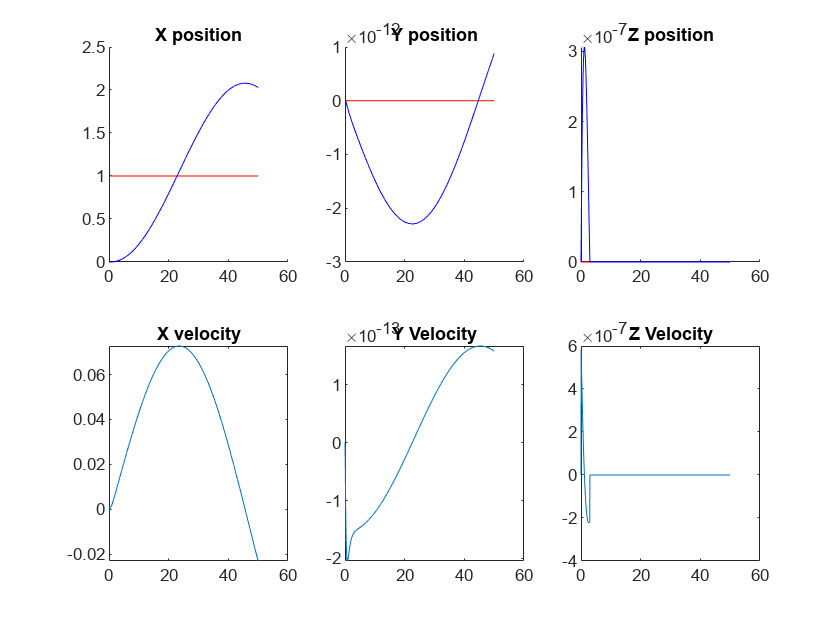


figure
title("Position history")
draw_position_history(t_space, r_hist, rdot_hist, ones(size(r_hist)) .* r_r);

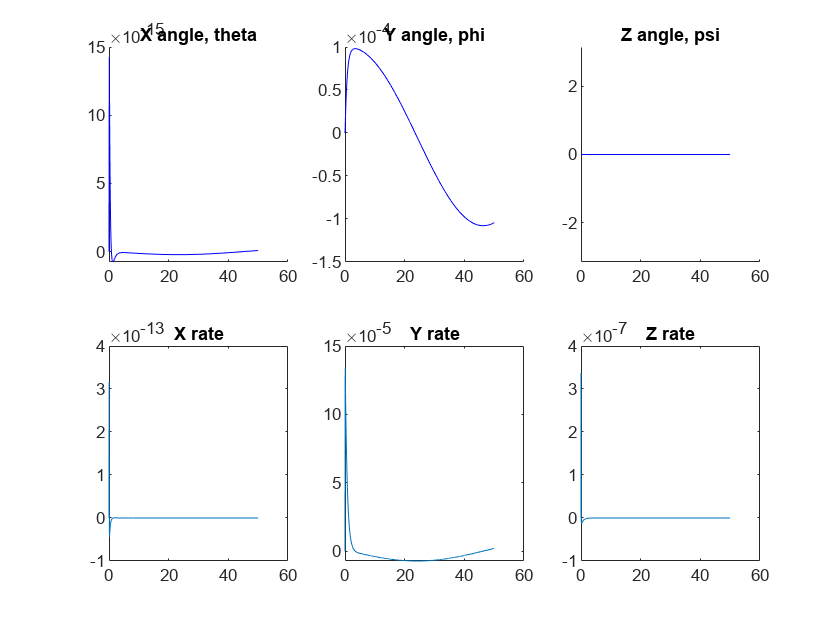


figure
title("Attitude history")
draw_attitude_history(t_space, q_hist, omega_hist, ones(size(q_hist)) .* q_r);

## Functions

function draw_position_history(t_space, v1, v2, r_r)
	subplot(2, 3, 1)
	hold on
	plot(t_space, r_r(1, :), 'r')
	plot(t_space, v1(1, :), 'b')
	title("X position")
	
	subplot(2, 3, 4)
	plot(t_space, v2(1, :))
	title("X velocity")
	
	subplot(2, 3, 2)
	hold on
	plot(t_space, r_r(2, :), 'r')
	plot(t_space, v1(2, :), 'b')
	title("Y position")

	subplot(2, 3, 5)
	plot(t_space, v2(2, :))
	title("Y Velocity")

	subplot(2, 3, 3)
	hold on
	plot(t_space, r_r(3, :), 'r')
	plot(t_space, v1(3, :), 'b')
	title("Z position")

	subplot(2, 3, 6)
	plot(t_space, v2(3, :))
	title("Z Velocity")
end

function draw_attitude_history(t_space, v1, v2, q_r)
	subplot(2, 3, 1)
	hold on
	plot(t_space, q_r(1), 'r')
	plot(t_space, v1(1,:), 'b')
% 	ylim([-pi, pi])
	title("X angle, theta")
	
	subplot(2, 3, 4)
	plot(t_space, v2(1,:))
	title("X rate")
	
	subplot(2, 3, 2)
	hold on
	plot(t_space, q_r(2), 'r')
	plot(t_space, v1(2,:), 'b')
% 	ylim([-pi, pi])
	title("Y angle, phi")

	subplot(2, 3, 5)
	plot(t_space, v2(2,:))
	title("Y rate")

	subplot(2, 3, 3)
	hold on
	plot(t_space, q_r(3), 'r')
	plot(t_space, v1(3,:), 'b')
	ylim([-pi, pi])
	title("Z angle, psi")

	subplot(2, 3, 6)
	plot(t_space, v2(3,:))
	title("Z rate")
end

function [dr, ddr, dq, do] = Rufous_Dynamics(r, rdot, q, omega, u, alpha, beta, Kt)
	m = 5;
	g = 9.81;
	l = 0.1;
	I = [1 0 0; 0 1 0; 0 0 0.1];

	u = max(u, [0; 0; 0; 0]);

	dr = rdot;
	ddr = Rufous_Thrust(q, u, Kt) - [0; 0; m * g] + [alpha; beta; 0];

	dq = omega;
	do = I \ (-tilde_op(omega) * I * omega + Rufous_Torque(u, Kt, l));
end

function Tp = Rufous_Thrust(q, u, Kt)
	Rnb = euler_angles_to_dcm(-q);
	z_hat_b = Rnb \ [0; 0; 1];
	Tp = Kt * sum(u.^2) * z_hat_b;
end

function Taup = Rufous_Torque(u, Kt, l)
	Taup = Kt * l * [1 0 -1 0; 0 -1 0 1; -1 1 -1 1] * u.^2;
end

function DCM = euler_angles_to_dcm(q)
	Rx = [1 0 0; 0 cos(q(1)) -sin(q(1)); 0 sin(q(1)) cos(q(1))];
	Ry = [cos(q(2)) 0 sin(q(2)); 0 1 0; -sin(q(2)) 0 cos(q(2))];
	Rz = [cos(q(3)) -sin(q(3)) 0; sin(q(3)) cos(q(3)) 0; 0 0 1];
	DCM = Rz * Ry * Rx;
end

function m = tilde_op(v)
	m = [0 -v(3) v(2); v(3) 0 -v(1); -v(2) v(1) 0];
end